%develope the code pipeline to process lfp data
global MONKEYDIR
MONKEYDIR = 'C:/Users/Orsborn Lab/OneDrive - UW/projects/Brain EEG/data';
addpath(genpath([MONKEYDIR '/m/']))
drive_base = 'LM1_ECOG';

%get sessions for 'drive' of interest
driveSessions = makeDriveDatabase(drive_base,{'180322','180328'});

Sessions = cat(1, driveSessions{:});
driveNames = Sessions(:,3);
driveNameAnalyze = {'LM1_ECOG_3'};
useSess          = ismember(driveNames, driveNameAnalyze);
DayAnalyze = Sessions(useSess,1);


%develope the code for single day
%trial load info
trialInfo.sequence_random = 1;
trialInfo.filterAcq = 1;
trialInfo.filterAcq_time = 5;

trialInfo.tBefore = -1.2e3;
trialInfo.tAfter  = 1e3;
trialInfo.timeReachStart = abs(trialInfo.tBefore);
trialInfo.trig = 'ReachStart';
trialInfo.lfpType = 'lfp';
trialInfo.Fs_lfp = 1000;

trialInfo.proc_electrodes = 1:243;

%parameters to
feaParams.freqBands = [0 12;12 38;38 80;80 200];
feaParams.timeROIs = [-0.2 0;0 0.2] %in seconds

feaParams = struct with fields:
    freqBands: [4×2 double]
     timeROIs: [2×2 double]



%use constant target
selectedfile = 'C:\Users\Orsborn Lab\OneDrive - UW\projects\Brain EEG\code\posTargets_180328.mat';
load(selectedfile)

%we load the regular trials
SessAnalyze = Sessions(useSess,:);
nSess = size(SessAnalyze,1);

%load the frequency spectrum
freqParams.tapers = [0.2 5];
freqParams.Fs = 1000;
freqParam.dn = 0.02;
freqParams.contFlag = 1;
freqParams.freqRange = [0 200]

freqParams = struct with fields:
       tapers: [0.2000 5]
           Fs: 1000
     contFlag: 1
    freqRange: [0 200]




class_results = nan(nSess,length(trialInfo.proc_electrodes));

Sessions_empty = [];
%remove any empty sessions
for iD=1:nSess
    
    trFN = [MONKEYDIR '/' DayAnalyze{iD} '/mat/Trials.mat'];
    load(trFN,'Trials')
    
    %filter out trials
    if trialInfo.sequence_random
        v = [Trials.SequenceRandom];
        Trials = Trials(v ==1);
    end
    if isempty(unique({Trials.Rec}))
        Sessions_empty = [Sessions_empty iD];
        disp(['Empty trials for day: ' DayAnalyze{iD}])
    end
    
    day_recs{iD,1} = unique({Trials.Rec});
    day_recs{iD,2} = {DayAnalyze{iD}};
    
end

Empty trials for day: 180325



Sessions(Sessions_empty,:) = [];

%the main processing loop

trLfpData_spec = [];

for iD=1:nSess
    
    trFN = [MONKEYDIR '/' DayAnalyze{iD} '/mat/Trials.mat'];
    load(trFN,'Trials')
    
    trialInfo.sessName =  DayAnalyze{iD};
    trialInfo.depthProfile = (Trials(1).Depth{1,2})'; % in micron
    
    %filter out trials
    if trialInfo.sequence_random
        v = [Trials.SequenceRandom];
        Trials = Trials(v ==1);
    end
    if trialInfo.filterAcq
        stopToAcq = [Trials.ReachStop] - [Trials.TargAq];
        v = abs(stopToAcq) <= trialInfo.filterAcq_time;
        Trials = Trials(v);
    end
    trialInfo.num_trials = length(Trials);
    
    
    %load the trials
    %first load an experiment trial
    expFN = [MONKEYDIR '/' DayAnalyze{iD} '/' Trials(1).Rec '/rec' Trials(1).Rec '.experiment.mat'];
    load(expFN,'experiment')
    
    driveNameAnalyze = 'LM1_ECOG_3';
    drive_idx = 1; %1 for ECOG and 2 for SC3
    dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
    data_ECOG = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
    
    %implement common averaging filter
    data_ECOG_mean = mean(data_ECOG,2);
    data_ECOG = data_ECOG - repmat(data_ECOG_mean,1,size(data_ECOG,2),1);
    
    driveNameAnalyze = 'LM1_SC32_1';
    drive_idx = 2; %1 for ECOG and 2 for SC32
    dataParam.eList = [experiment.hardware.microdrive(drive_idx).electrodes.channelid];
    data_SC32 = trialLfp(Trials,driveNameAnalyze,dataParam.eList,[],trialInfo.trig,[trialInfo.tBefore,trialInfo.tAfter],trialInfo.lfpType,MONKEYDIR);
    
    trLfpData = cat(2,data_ECOG, data_SC32);
    
    clear data_SC32
    clear data_ECOG
    
    %do target sorting
    [Pos, targids] = calcSeqReachTarg(Trials);
    Pos_Seq_1 = squeeze(Pos(:,2,:));
    trial_TargetAssigned = assignTaskNumber(Pos_Seq_1_unique,Pos_Seq_1);
    
    %do time frequency analysis on each of the electrode
    for ti = 1:trialInfo.num_trials
        
        %figure out normalization period
        timeAqGo = Trials(ti).StartAq - Trials(ti).ReachStart + trialInfo.timeReachStart;
        timeTargsOn = Trials(ti).TargsOn - Trials(ti).ReachStart + trialInfo.timeReachStart;
        
        if timeAqGo <=0 || timeTargsOn <=0
            disp([DayAnalyze{iD} ': Trial ' num2str(ti)])
            continue
        end
        
        for e_index = 1:length(trialInfo.proc_electrodes) %look at only 1 electrode for now
            ei = trialInfo.proc_electrodes(e_index);
            dataTemp = squeeze(trLfpData(ti,ei,:));
            dataTemp = dataTemp / norm(dataTemp);
            
            dataTemp = dataTemp(timeAqGo:timeTargsOn);
            %do frequency calculation
            dat = dataTemp';
            [s, freq] = tfspec(dat, freqParams.tapers, freqParams.Fs, freqParam.dn, [], [], [], [], freqParams.contFlag);
            
            s_n_mean = squeeze(mean(s));
            s_n_std = squeeze(std(s));
            
            %reload the data
            dataTemp = squeeze(trLfpData(ti,ei,:));
            dataTemp = dataTemp / norm(dataTemp);
            dat = dataTemp';
            [s, freq] = tfspec(dat, freqParams.tapers, freqParams.Fs, freqParam.dn, [], [], [], [], freqParams.contFlag);
            
            %get z-score
            sN = size(s,1);
            s_z = (s - repmat(s_n_mean,sN,1)) ./ repmat(s_n_std,sN,1);
            
            trLfpData_spec(ti,e_index,:,:) = s_z;
            
        end
    end
    disp(['Finished: ' DayAnalyze{iD} ' spectrum calc'])
    
    %get the feature vector
    
    s_length = size(trLfpData_spec,3);
    s_timePoints = freqParams.tapers(1)* 0.5 +(1:s_length)*freqParams.tapers(1) * 0.1 ...
        + trialInfo.tBefore / 1000;
    trLfpData_spec_feature = [];
    
    for ti = 1:trialInfo.num_trials
        for e_index = 1:length(trialInfo.proc_electrodes)
            
            s_z = squeeze(trLfpData_spec(ti,e_index,:,:));
            s_z_feature = [];
            for time_i = 1:size(feaParams.timeROIs,1)
                time_indices = find((s_timePoints >= feaParams.timeROIs(time_i,1) ) & (s_timePoints <= feaParams.timeROIs(time_i,2) ));
                
                for fi = 1:size(feaParams.freqBands,1)
                    freqRangeIndex  = cal_index_freq(freq,feaParams.freqBands(fi,1),feaParams.freqBands(fi,2));
                    s_z_feature(fi,time_i) =  mean(mean(s_z(time_indices,freqRangeIndex)));
                end
            end
            trLfpData_spec_feature(ti,e_index,:) = reshape(s_z_feature,1,[]);
        end
    end
    
    %do classification
    for ei = 1:length(trialInfo.proc_electrodes)
        try
            meas = squeeze(trLfpData_spec_feature(:,ei,:));
            MdlLinear = fitcdiscr(meas,trial_TargetAssigned,'DiscrimType',"quadratic");
            grouphat = predict(MdlLinear,meas);
            
            trialInfo.feaResults(ei) = sum(trial_TargetAssigned == grouphat) / length(trial_TargetAssigned);
            trialInfo.classifier{ei} = MdlLinear;
            
        catch ME
            disp(ME.message)
            trialInfo.feaResults(ei) = nan;
            trialInfo.classifier{ei} = nan;
        end
    end
    class_results(iD,:) = trialInfo.feaResults;
    
    
    saveFn = [MONKEYDIR '/' DayAnalyze{iD} '/mat/results_0122.mat'];
    save(saveFn,"trialInfo","trial_TargetAssigned","trLfpData_spec_feature");
    trialInfo_all(iD) = trialInfo;
    
    disp(['Finished: ' DayAnalyze{iD} ' Classification'])
    disp('done')
    
end
save('results_all_allelectrodes',"trialInfo_all","class_results")

there is a bug loading the data for days before 180328

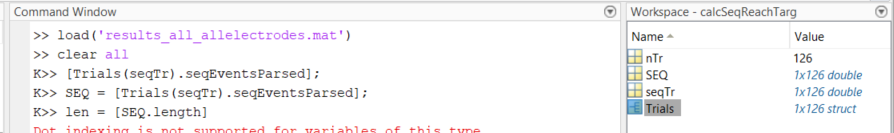

Quickly look at the data

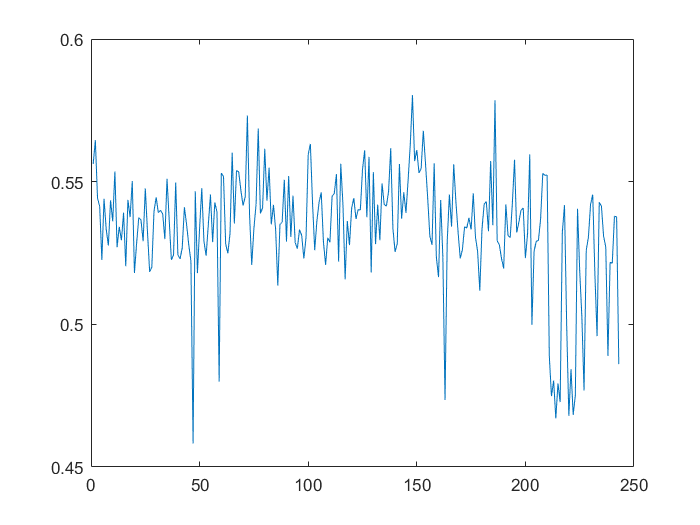

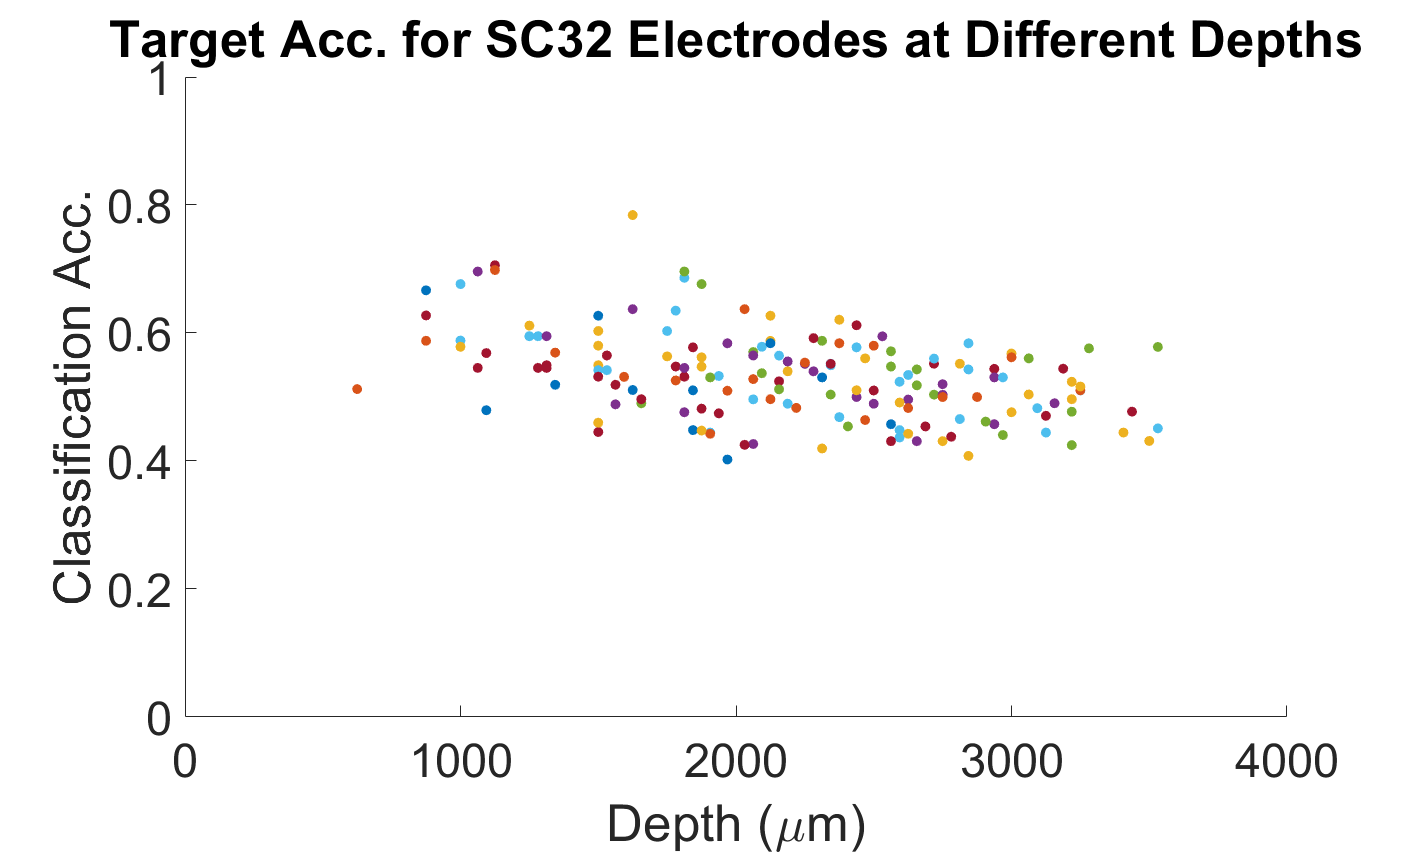


%plot the results

%electrodes_SC32_index = find(trialInfo_all(1).proc_electrodes > 211)
electrodes_SC32_index = 212:243;
%electrodes_SC32 = trialInfo_all(1).proc_electrodes(electrodes_SC32_index) - 211;
electrodes_SC32 = 1:32;
depthProfiles = [trialInfo_all(:).depthProfile]';

figure
plot(nanmean(class_results))

figure('units','normalized','outerposition',[0 0 0.75 0.75])
%plot the ECOG electrodes
hold on


for ei = 1:length(electrodes_SC32_index)
    
    depthProfiles_temp = depthProfiles(:,electrodes_SC32(ei));
    class_results_temp = class_results(:,electrodes_SC32_index(ei));
    
    scatter(depthProfiles_temp(depthProfiles_temp > 0)-3000,class_results_temp(depthProfiles_temp > 0),'filled')
end
xlabel('Depth (\mum)')
ylabel('Classification Acc.')
axis([0 4000 0 1])
title('Target Acc. for SC32 Electrodes at Different Depths')
set(gca,'fontSize',28)
hold off
print(gcf, 'centerout_lda_SC32.jpg', '-djpeg', '-r600');

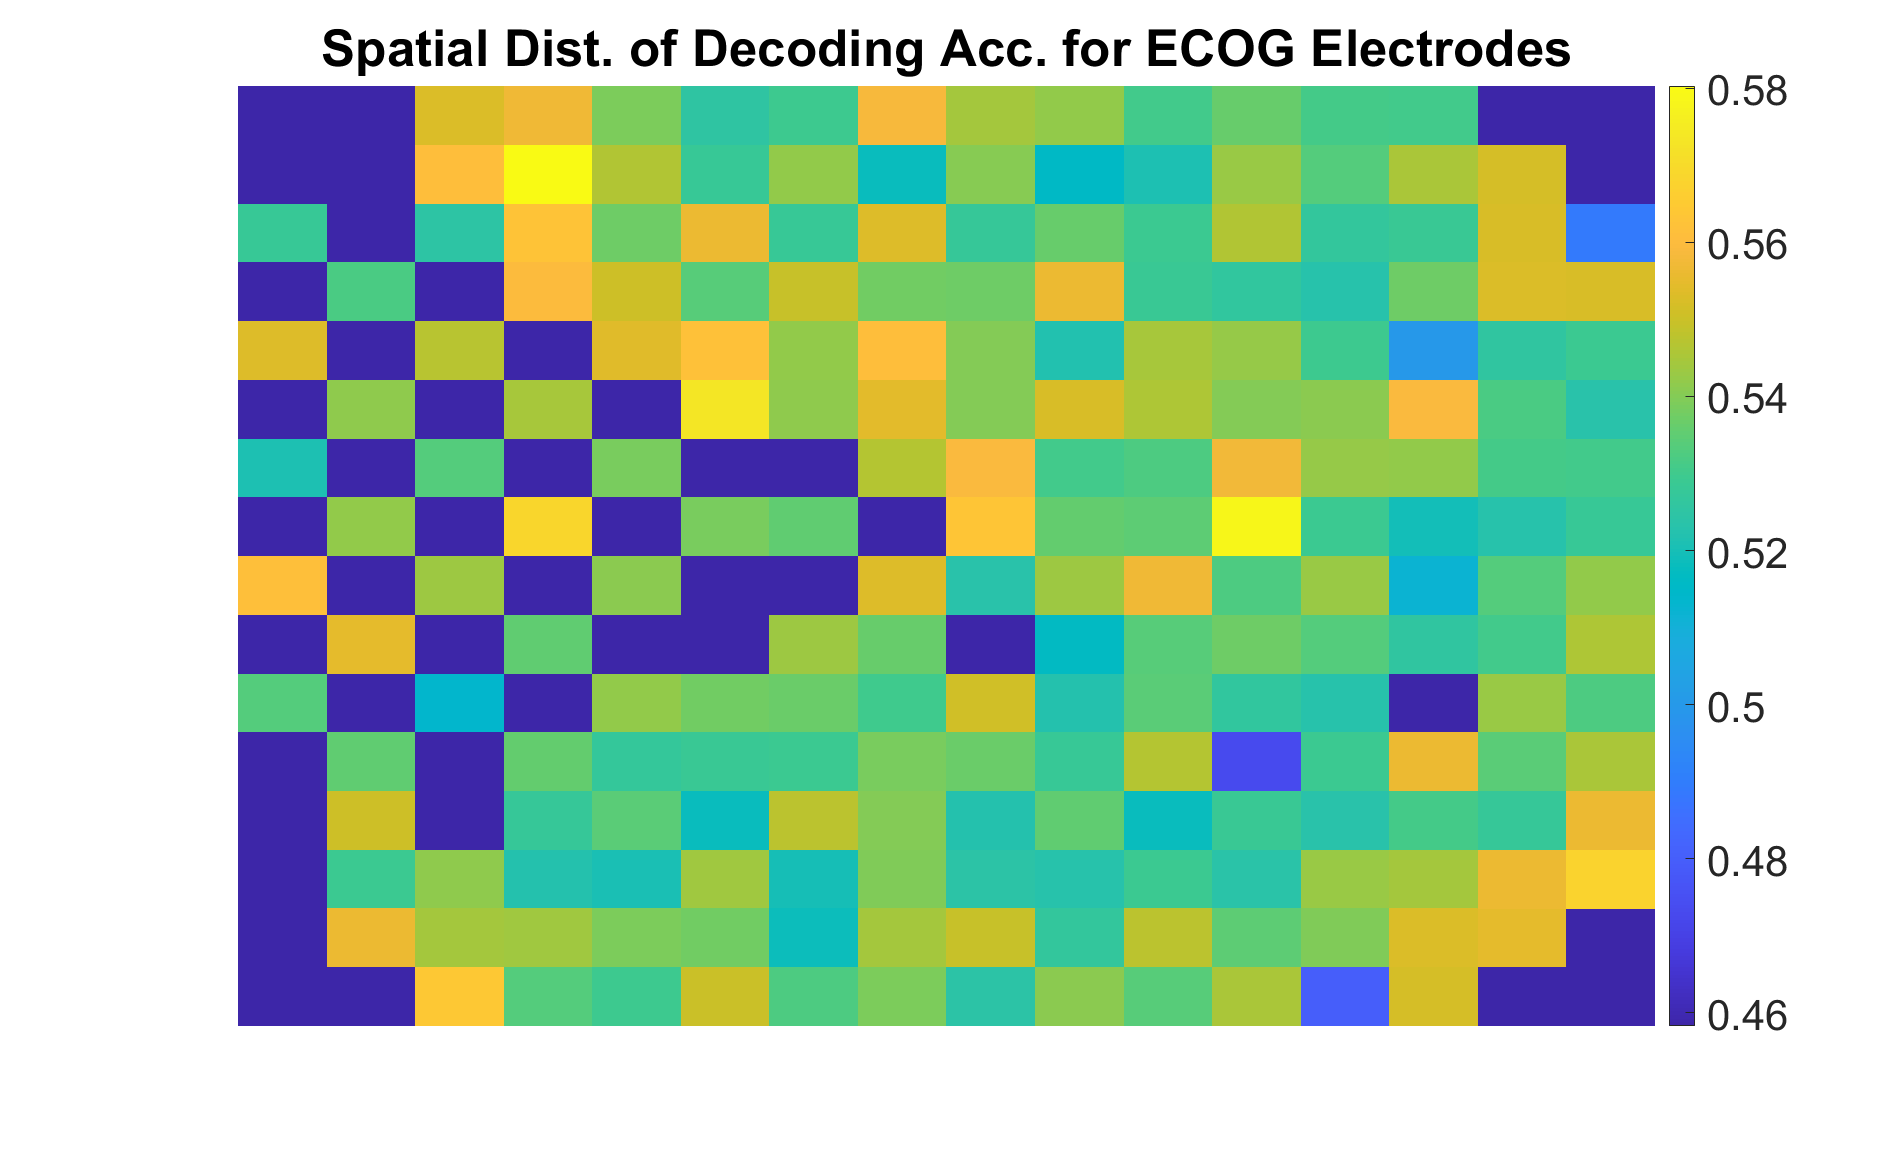

%load 20180329.003.experiment
%load 180329/mat/trials
drive_idx = 1;
freqRange = [0 12];

[map,mapInfo]= scatterToMatrix(P_chamber,squeeze(mean(class_results(:,1:211)))');
imagesc(map')
axis xy
colorbar
title('Spatial Dist. of Decoding Acc. for ECOG Electrodes')

axis off
set(gca,'fontSize',28)
print(gcf, 'centerout_lda_ECOG_dist.jpg', '-djpeg', '-r600');

The ECOG accuracies are plotted at 3000. The SC32 electrodes are plotted against their depths. There could be a decreasing trend.  We don't have the sequence data for the first days.

%build the feature vector

%parameters to
feaParams.freqBands = [0 12;12 38;38 80;80 200];
feaParams.timeROIs = [-0.2 0;0 0.2]; %in seconds

s_length = size(trLfpData_spec,3);
s_timePoints = freqParams.tapers(1)* 0.5 +(1:s_length)*freqParams.tapers(1) * 0.1 ...
    + trialInfo.tBefore / 1000;
time_indices = find((s_timePoints >= feaParams.timeROI(1) ) & (s_timePoints <= feaParams.timeROI(2) ));
trLfpData_spec_feature = [];

for ti = 1:trialInfo.num_trials
    for e_index = 1:length(trialInfo.proc_electrodes)
        
        s_z = squeeze(trLfpData_spec(ti,e_index,:,:));
        s_z_feature = [];
        for time_i = 1:size(feaParams.timeROIs,1)
            time_indices = find((s_timePoints >= feaParams.timeROIs(time_i,1) ) & (s_timePoints <= feaParams.timeROIs(time_i,2) ));
            
            for fi = 1:size(feaParams.freqBands,1)
                freqRangeIndex  = cal_index_freq(freq,feaParams.freqBands(fi,1),feaParams.freqBands(fi,2));
                s_z_feature(fi,time_i) =  mean(mean(s_z(time_indices,freqRangeIndex)));
            end
        end
        trLfpData_spec_feature(ti,e_index,:) = reshape(s_z_feature,1,[]);
    end
end
disp('Done!')

%look at different data
plotParams.tickSpacing = 10;

s_length = size(trLfpData_spec,3);
s_timePoints = freqParams.tapers(1)* 0.5 +(1:s_length)*freqParams.tapers(1) * 0.1 ...
    + trialInfo.tBefore / 1000;
time_indices = find((s_timePoints >= -0.4 ) & (s_timePoints <= 1 ));

xticklabels = round(s_timePoints(time_indices),2);
xticklabels = xticklabels(1:plotParams.tickSpacing:end);
xticks = linspace(1,length(time_indices), ...
    numel(xticklabels));

for e_index = 1:length(proc_electrodes)
    figure
    ei = proc_electrodes(e_index);
    for targ_i = 1:7
        subplot(2,4,targ_i)
        targ_i_index = find(trial_TargetAssigned == targ_i);
        imagesc(squeeze(mean(trLfpData_spec(targ_i_index,e_index,time_indices,freqRangeIndex )))')
        title(['E' num2str(ei) ' Target ' num2str(targ_i)])
        
        set(gca, 'xTick', xticks, 'xTickLabel', xticklabels)
        
        axis xy
        caxis([-10 10])
    end
    subplot(2,4,8)
    caxis([-6 6])
    axis off
    colorbar
end







